## **External Replication Model HCP in AOMIC **

## **Part 1**

This is Part 1 of the external replication of the Linear Regression Model built in the HCP that is then tested in the AOMIC. It creates a positive and negative NMA

for the AOMIC according to the Node-Measure Assignments in the HCP. 

Before running this script: 

- HCP_compute_coupling_measures

- run HCP_NMAs_whole_sample

**1) Create a cell that contains for each subject a vector of 8 predictors for each node **

for i = 1:567
    x = final_r_all_AOMIC_567_new{i,1};
    for j = 1:358
    Node_all_baseline_AOMIC_weighted_only{i,j} = x(j,:);
    end
end


**2) Create cell that contains information from all subjects and all coupling measures for all nodes seaparetely (567*8)**

% extract for each collumn die 8 rows from each row and put them together in a matrix (--> I need 567*8 Matrix for each Node)

n = size(Node_all_baseline_AOMIC_weighted_only,2);
All_Nodes_complete_baseline_AOMIC_weighted_only = cell(1,n);
for j = 1:n
    All_Nodes_complete_baseline_AOMIC_weighted_only{j} = vertcat(Node_all_baseline_AOMIC_weighted_only{:,j});
end

2.1.) Fix Problems with Node 171 & Node 343

Convert all Isnan Values to 0 (so that the Code works) 

% Node 38 
all_values_171 = All_Nodes_complete_baseline_AOMIC_weighted_only{1,171};
all_values_171(isnan(all_values_171)) = 0;

All_Nodes_complete_baseline_AOMIC_weighted_only{1,171} = all_values_171;


% Node 58 
all_values_343 = All_Nodes_complete_baseline_AOMIC_weighted_only{1,343};
all_values_343(isnan(all_values_343)) = 0;

All_Nodes_complete_baseline_AOMIC_weighted_only{1,343} = all_values_343;

**3) Build a positive and a negative NMA according to the NMAs from the HCP **

Node-Measure Affiliation from HCP

best_performing_measure_per_node_pos_HCP_wei;

best_performing_measure_per_node_neg_HCP_wei; 


**4) Extract the coupling values for the positive NMA**

Best_case_scenario_r_values_pos_AOMIC = zeros(358,567);

for i = 1:358
    index = best_performing_measure_per_node_pos_HCP_wei(i);
    Best_scenario_node_values = All_Nodes_complete_baseline_AOMIC_weighted_only{1,i}(:,index);
    
    Best_case_scenario_r_values_pos_AOMIC(i,:) = Best_scenario_node_values';
end

Best_case_scenario_r_values_pos_AOMIC = Best_case_scenario_r_values_pos_AOMIC';

**5) Extract the coupling values for the negative NMA**

Best_case_scenario_r_values_neg_AOMIC = zeros(358,567);

for i = 1:358
    index = best_performing_measure_per_node_neg_HCP_wei(i);
    Best_scenario_node_values_neg = All_Nodes_complete_baseline_AOMIC_weighted_only{1,i}(:,index); 
    
    Best_case_scenario_r_values_neg_AOMIC(i,:) = Best_scenario_node_values_neg';
end

Best_case_scenario_r_values_neg_AOMIC = Best_case_scenario_r_values_neg_AOMIC';

## **Part 2**

This is Part 2 of the external replication of the Linear Regression Model built in the HCP that is then tested in the AOMIC. It creates the Linear Regression Model in the

HCP and tests for its prediction of cognitive ability scores in the AOMIC sample. This part specifically tests the ,odel with a permutation test. Intelligence scores are permuted and the model predicts those 

permuted scores. Model performance is assessed by comparing model performance on the permuted data to model performance on the actual data. 

for permutation_test_round = 1:1000

**1) Build Model in HCP **

Assign the Behavioral Variables 

Intelligence_HCP = HCP_behavioral_1030.G_Factor;
ALter_HCP = HCP_behavioral_1030.Age;
Gender_HCP = HCP_behavioral_1030.("Gender num");
Motion_HCP = HCP_behavioral_1030.Mean_mean_FD;
Handedness_HCP = HCP_behavioral_1030.Handedness;

 Convert scores into z-scores

Alter_HCP_z = normalize(ALter_HCP);
Gender_HCP_z = normalize(Gender_HCP);
Motion_HCP_z = normalize(Motion_HCP);
Handedness_HCP_z = normalize(Handedness_HCP);

Intelligence_HCP_z = normalize(Intelligence_HCP);
Intelligence_HCP_rand = Intelligence_HCP_z(randperm(length(Intelligence_HCP_z)));

 Regress out the confounding Variables from Intelligence

confounds = [Alter_HCP_z Gender_HCP_z Motion_HCP_z Handedness_HCP_z];

mdl_regress_HCP_intelligence_z_rand = fitlm(confounds,Intelligence_HCP_rand);
residuals_intelligence_HCP_z_rand = mdl_regress_HCP_intelligence_z_rand.Residuals.Raw;

Retrieve NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_r_values_pos_HCP;
Best_case_scenario_r_values_neg = Best_case_scenario_r_values_neg_HCP;

Take the Mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Positive_all = normalize(Positive_all);
Negative_all = normalize(Negative_all);

 Regress out the confounding Variables from positive BCS 

confounds = [Alter_HCP_z Gender_HCP_z Motion_HCP_z Handedness_HCP_z];

mdl_regress_HCP_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_HCP = mdl_regress_HCP_pos_bcs.Residuals.Raw;

mdl_regress_HCP_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_HCP = mdl_regress_HCP_neg_bcs.Residuals.Raw;

 Build the actual Model

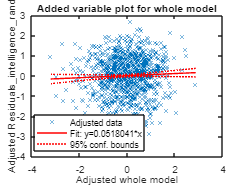

Model_Matrix = [residuals_pos_HCP residuals_neg_HCP residuals_intelligence_HCP_z_rand];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_bcs', 'residuals_neg_bcs','Residuals_intelligence_rand'};

mdl_pos_neg_bcs_HCP_rand = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_HCP_rand);

**2) Test Model in AOMIC **

Intelligence_AOMIC = AOMIC_behavioral_567_numerical.IST_intelligence_total;
Alter_AOMIC = AOMIC_behavioral_567_numerical.age;
Gender_AOMIC = AOMIC_behavioral_567_numerical.sex_num;
Motion_AOMIC = AOMIC_behavioral_567_numerical.("Mean FD");
Handedness_AOMIC = AOMIC_behavioral_567_numerical.handedness_num;

Convert scores into z-scores

ALter_AOMIC_z = normalize(Alter_AOMIC);
Gender_AOMIC_z = normalize(Gender_AOMIC);
Motion_AOMIC_z = normalize(Motion_AOMIC);
Handedness_AOMIC_z = normalize(Handedness_AOMIC);

Intelligence_AOMIC_z = normalize(Intelligence_AOMIC);

 Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)


confounds = [ALter_AOMIC_z Gender_AOMIC_z Motion_AOMIC_z Handedness_AOMIC_z];
int_pred = predict(mdl_regress_HCP_intelligence_z_rand,confounds);

residuals_intelligence_AOMIC_z = (Intelligence_AOMIC_z - int_pred );


Retrieve NMAs 

Best_case_scenario_r_values_pos = Best_case_scenario_r_values_pos_AOMIC;

Best_case_scenario_r_values_neg = Best_case_scenario_r_values_neg_AOMIC;

Retrieve NMAs

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Positive_all = normalize(Positive_all);
Negative_all = normalize(Negative_all);

Regress out the confounding Variables 

confounds = [ALter_AOMIC_z Gender_AOMIC_z Motion_AOMIC_z Handedness_AOMIC_z];


Positive_all_pred = predict(mdl_regress_HCP_pos_bcs,confounds);

residuals_pos = (Positive_all - Positive_all_pred);


Negative_all_pred = predict(mdl_regress_HCP_neg_bcs,confounds);

residuals_neg = (Negative_all - Negative_all_pred);

Xnew = [residuals_pos residuals_neg];
ypred = predict(mdl_pos_neg_bcs_HCP_rand,Xnew);

**3) Correlate predicted with observed scores**

[r,pval] = corr(ypred,residuals_intelligence_AOMIC_z)

r = -0.0879

pval = 0.0364

r = -0.0406

pval = 0.3343

r = 0.0830

pval = 0.0481

r = -0.1203

pval = 0.0041

r = -0.0858

pval = 0.0412

r = 0.1083

pval = 0.0099

r = -0.0621

pval = 0.1398

r = -0.0512

pval = 0.2231

r = 0.0697

pval = 0.0971

r = -0.1059

pval = 0.0116

r = -0.0578

pval = 0.1696

r = -0.0450

pval = 0.2845

r = 0.1299

pval = 0.0019

r = 0.1183

pval = 0.0048

r = -0.0898

pval = 0.0326

r = -0.0761

pval = 0.0702

r = -0.1229

pval = 0.0034

r = 0.0369

pval = 0.3808

r = -0.0163

pval = 0.6984

r = -0.0721

pval = 0.0865

r = -0.0586

pval = 0.1637

r = 0.1276

pval = 0.0023

r = 0.1240

pval = 0.0031

r = 0.1067

pval = 0.0110

r = 0.1145

pval = 0.0064

r = 0.0677

pval = 0.1071

r = -0.0923

pval = 0.0281

r = -0.0722

pval = 0.0860

r = -0.0992

pval = 0.0181

r = -0.0710

pval = 0.0911

r = -0.1086

pval = 0.0097

r = 0.0350

pval = 0.4057

r = -0.1142

pval = 0.0065

r = 0.0209

pval = 0.6187

r = 0.0637

pval = 0.1296

r = -0.0094

pval = 0.8241

r = -0.0776

pval = 0.0648

r = 0.0481

pval = 0.2527

r = 0.0991

pval = 0.0182

r = 0.0836

pval = 0.0465

r = 0.0575

pval = 0.1712

r = -0.0043

pval = 0.9189

r = -0.1092

pval = 0.0093

r = 0.0185

pval = 0.6611

r = -0.0678

pval = 0.1069

r = 0.1131

pval = 0.0070

r = -0.0273

pval = 0.5166

r = -0.0012

pval = 0.9763

r = -0.0272

pval = 0.5180

r = -0.0667

pval = 0.1129

r = -0.0082

pval = 0.8450

r = -0.0922

pval = 0.0281

r = -0.0985

pval = 0.0190

r = -0.1224

pval = 0.0035

r = -0.0650

pval = 0.1218

r = 0.0972

pval = 0.0206

r = -0.1196

pval = 0.0044

r = -0.0980

pval = 0.0196

r = -0.1217

pval = 0.0037

r = 0.0542

pval = 0.1977

r = 0.0701

pval = 0.0952

r = -0.0404

pval = 0.3373

r = 0.1131

pval = 0.0070

r = 0.0863

pval = 0.0400

r = 0.0909

pval = 0.0305

r = -0.0868

pval = 0.0389

r = 0.0855

pval = 0.0418

r = -0.0980

pval = 0.0196

r = 0.1151

pval = 0.0061

r = 0.1088

pval = 0.0095

r = -0.1228

pval = 0.0034

r = 0.0701

pval = 0.0954

r = -0.0181

pval = 0.6676

r = -0.0090

pval = 0.8303

r = 0.0067

pval = 0.8735

r = -0.1128

pval = 0.0072

r = -0.0659

pval = 0.1173

r = 0.0653

pval = 0.1203

r = 0.1206

pval = 0.0040

r = -0.1115

pval = 0.0079

r = 0.1047

pval = 0.0126

r = -0.1283

pval = 0.0022

r = -0.0521

pval = 0.2152

r = -0.0324

pval = 0.4406

r = 0.0155

pval = 0.7132

r = -0.0154

pval = 0.7147

r = 0.0783

pval = 0.0623

r = -0.1212

pval = 0.0039

r = 0.0318

pval = 0.4498

r = 0.1069

pval = 0.0109

r = 0.1102

pval = 0.0086

r = -0.0527

pval = 0.2102

r = 0.0997

pval = 0.0175

r = -0.1128

pval = 0.0072

r = 0.0296

pval = 0.4815

r = -0.0168

pval = 0.6900

r = -0.0104

pval = 0.8051

r = -0.0963

pval = 0.0218

r = 0.0213

pval = 0.6125

r = -0.1004

pval = 0.0168

r = 0.1106

pval = 0.0084

r = -0.0502

pval = 0.2326

r = 0.0814

pval = 0.0527

r = -0.0030

pval = 0.9440

r = -0.0098

pval = 0.8156

r = 0.0158

pval = 0.7066

r = -0.1226

pval = 0.0035

r = 0.1275

pval = 0.0024

r = 0.1181

pval = 0.0048

r = 0.0138

pval = 0.7436

r = 0.0452

pval = 0.2830

r = 0.0379

pval = 0.3679

r = -0.0390

pval = 0.3534

r = 0.0151

pval = 0.7203

r = -0.0110

pval = 0.7943

r = 0.0852

pval = 0.0426

r = -0.0994

pval = 0.0179

r = -0.0783

pval = 0.0626

r = 0.0298

pval = 0.4792

r = 0.0419

pval = 0.3193

r = 0.0566

pval = 0.1784

r = -0.0283

pval = 0.5019

r = -0.1073

pval = 0.0106

r = 0.0422

pval = 0.3158

r = 0.0742

pval = 0.0777

r = -0.0248

pval = 0.5554

r = 0.1175

pval = 0.0051

r = -0.0896

pval = 0.0330

r = -0.0860

pval = 0.0407

r = 0.1142

pval = 0.0065

r = 0.0941

pval = 0.0250

r = -0.0816

pval = 0.0521

r = 0.1174

pval = 0.0051

r = 0.0408

pval = 0.3321

r = 0.0081

pval = 0.8477

r = -0.0820

pval = 0.0509

r = 0.0531

pval = 0.2064

r = 0.0981

pval = 0.0195

r = -0.0623

pval = 0.1384

r = -0.1055

pval = 0.0120

r = 0.1001

pval = 0.0171

r = 0.0142

pval = 0.7354

r = 0.0911

pval = 0.0301

r = -0.0014

pval = 0.9727

r = -0.0311

pval = 0.4594

r = -0.1078

pval = 0.0102

r = 0.0998

pval = 0.0174

r = -0.1154

pval = 0.0059

r = 0.0907

pval = 0.0309

r = -0.0720

pval = 0.0867

r = 0.1236

pval = 0.0032

r = 0.0480

pval = 0.2536

r = 0.1100

pval = 0.0087

r = 0.0757

pval = 0.0717

r = 0.0672

pval = 0.1100

r = -0.0769

pval = 0.0674

r = -0.0410

pval = 0.3299

r = -0.1108

pval = 0.0083

r = 0.0626

pval = 0.1366

r = 0.0099

pval = 0.8149

r = -0.1197

pval = 0.0043

r = -0.1173

pval = 0.0052

r = -0.0955

pval = 0.0230

r = 0.0629

pval = 0.1345

r = -0.0938

pval = 0.0255

r = 0.0365

pval = 0.3854

r = -0.0880

pval = 0.0361

r = 2.8099e-04

pval = 0.9947

r = -0.1080

pval = 0.0101

r = -0.1249

pval = 0.0029

r = -0.0557

pval = 0.1855

r = 0.0263

pval = 0.5325

r = -0.0500

pval = 0.2345

r = -0.1025

pval = 0.0146

r = 0.1017

pval = 0.0154

r = 0.0510

pval = 0.2255

r = -0.0649

pval = 0.1228

r = 0.0148

pval = 0.7245

r = -9.2861e-04

pval = 0.9824

r = 0.0598

pval = 0.1547

r = 0.0327

pval = 0.4367

r = 0.1132

pval = 0.0070

r = -0.0759

pval = 0.0709

r = 0.0646

pval = 0.1243

r = 0.0898

pval = 0.0326

r = -0.0529

pval = 0.2086

r = 0.0506

pval = 0.2288

r = -0.0669

pval = 0.1117

r = -0.0979

pval = 0.0197

r = 0.0920

pval = 0.0285

r = -0.0912

pval = 0.0299

r = -0.1087

pval = 0.0096

r = -0.1169

pval = 0.0053

r = 0.0733

pval = 0.0812

r = -0.1068

pval = 0.0110

r = -0.0897

pval = 0.0328

r = -0.0251

pval = 0.5504

r = -0.0769

pval = 0.0671

r = 0.1138

pval = 0.0067

r = -0.1058

pval = 0.0117

r = 0.0692

pval = 0.0998

r = -0.0236

pval = 0.5742

r = 0.0637

pval = 0.1300

r = -0.0903

pval = 0.0316

r = -0.0885

pval = 0.0351

r = 0.0880

pval = 0.0363

r = -0.0396

pval = 0.3462

r = -0.1052

pval = 0.0122

r = 0.0926

pval = 0.0275

r = 0.0521

pval = 0.2159

r = 0.0595

pval = 0.1568

r = 0.0924

pval = 0.0278

r = -0.1142

pval = 0.0065

r = -0.0311

pval = 0.4596

r = -0.1084

pval = 0.0098

r = -0.1339

pval = 0.0014

r = 0.0488

pval = 0.2463

r = -0.0406

pval = 0.3346

r = 0.0915

pval = 0.0293

r = 0.1219

pval = 0.0037

r = -0.1205

pval = 0.0041

r = -0.0509

pval = 0.2260

r = 0.1085

pval = 0.0097

r = 0.0072

pval = 0.8635

r = -0.0308

pval = 0.4636

r = -0.0547

pval = 0.1930

r = -0.0990

pval = 0.0184

r = -0.0706

pval = 0.0931

r = 0.0981

pval = 0.0195

r = -0.1177

pval = 0.0050

r = 0.1067

pval = 0.0110

r = 0.0118

pval = 0.7784

r = -0.1052

pval = 0.0122

r = 0.1039

pval = 0.0133

r = -0.0279

pval = 0.5078

r = -0.1249

pval = 0.0029

r = -0.0038

pval = 0.9283

r = 0.0779

pval = 0.0638

r = 0.0292

pval = 0.4884

r = -0.0654

pval = 0.1199

r = 0.1120

pval = 0.0076

r = 0.0746

pval = 0.0758

r = -0.1014

pval = 0.0157

r = 0.0462

pval = 0.2723

r = -0.0933

pval = 0.0264

r = 0.0687

pval = 0.1021

r = -0.0621

pval = 0.1399

r = 0.0740

pval = 0.0781

r = 0.0447

pval = 0.2881

r = -0.0447

pval = 0.2876

r = -0.0301

pval = 0.4737

r = -0.0731

pval = 0.0820

r = -0.0980

pval = 0.0196

r = 0.0632

pval = 0.1329

r = -0.1209

pval = 0.0039

r = 0.0569

pval = 0.1760

r = 0.1163

pval = 0.0056

r = -0.0931

pval = 0.0266

r = 0.1251

pval = 0.0028

r = -0.1218

pval = 0.0037

r = -0.1122

pval = 0.0075

r = 0.1029

pval = 0.0143

r = -0.1189

pval = 0.0046

r = 0.0251

pval = 0.5514

r = 0.0788

pval = 0.0609

r = -0.0097

pval = 0.8179

r = -0.1114

pval = 0.0079

r = -0.1148

pval = 0.0062

r = 0.0081

pval = 0.8468

r = 0.1111

pval = 0.0081

r = 0.0344

pval = 0.4134

r = 0.0884

pval = 0.0353

r = 0.0974

pval = 0.0203

r = -0.0956

pval = 0.0229

r = -0.0828

pval = 0.0488

r = -3.5499e-04

pval = 0.9933

r = 0.1135

pval = 0.0068

r = 0.1184

pval = 0.0048

r = -0.0619

pval = 0.1412

r = -0.0723

pval = 0.0856

r = 0.0281

pval = 0.5036

r = -0.1123

pval = 0.0074

r = 0.0386

pval = 0.3591

r = 0.1009

pval = 0.0162

r = -0.0110

pval = 0.7929

r = 0.1103

pval = 0.0085

r = -0.1367

pval = 0.0011

r = 0.0711

pval = 0.0908

r = -0.1157

pval = 0.0058

r = -0.0836

pval = 0.0465

r = -0.1229

pval = 0.0034

r = 0.1115

pval = 0.0078

r = -0.0848

pval = 0.0436

r = 0.0984

pval = 0.0191

r = 0.1120

pval = 0.0076

r = 0.0811

pval = 0.0536

r = 0.0940

pval = 0.0252

r = 0.0473

pval = 0.2609

r = -0.0212

pval = 0.6141

r = 0.0300

pval = 0.4757

r = -0.0257

pval = 0.5421

r = -0.1044

pval = 0.0129

r = -0.1052

pval = 0.0122

r = -0.0060

pval = 0.8869

r = -0.0723

pval = 0.0855

r = 0.0200

pval = 0.6354

r = 0.1208

pval = 0.0040

r = 0.0626

pval = 0.1364

r = -0.0629

pval = 0.1344

r = 0.1050

pval = 0.0123

r = 0.0528

pval = 0.2095

r = -0.0996

pval = 0.0177

r = -0.0449

pval = 0.2857

r = -0.0392

pval = 0.3511

r = 0.0187

pval = 0.6562

r = -0.0220

pval = 0.6015

r = 0.1017

pval = 0.0154

r = 0.0705

pval = 0.0937

r = -0.0102

pval = 0.8093

r = 0.1174

pval = 0.0051

r = -0.0795

pval = 0.0585

r = 0.0674

pval = 0.1088

r = -0.0218

pval = 0.6039

r = 0.1081

pval = 0.0100

r = 0.0712

pval = 0.0903

r = -0.0492

pval = 0.2421

r = -0.1015

pval = 0.0156

r = 0.0127

pval = 0.7625

r = 0.0680

pval = 0.1058

r = 0.0545

pval = 0.1953

r = 0.0879

pval = 0.0365

r = 0.0075

pval = 0.8577

r = 0.0836

pval = 0.0466

r = 0.0833

pval = 0.0474

r = -0.0429

pval = 0.3076

r = 0.0707

pval = 0.0926

r = 0.0784

pval = 0.0623

r = 0.0737

pval = 0.0797

r = -0.0050

pval = 0.9055

r = 0.0282

pval = 0.5026

r = -0.0406

pval = 0.3341

r = 0.0555

pval = 0.1873

r = 0.0157

pval = 0.7100

r = 0.0534

pval = 0.2042

r = 0.0560

pval = 0.1827

r = 0.0961

pval = 0.0221

r = -0.0699

pval = 0.0964

r = 0.0655

pval = 0.1191

r = 0.0392

pval = 0.3510

r = 0.1162

pval = 0.0056

r = 0.1273

pval = 0.0024

r = 0.1212

pval = 0.0039

r = 0.0854

pval = 0.0420

r = 0.0893

pval = 0.0336

r = -0.0731

pval = 0.0820

r = 0.0487

pval = 0.2474

r = 0.1100

pval = 0.0088

r = -0.0550

pval = 0.1907

r = -0.1079

pval = 0.0101

r = 0.1008

pval = 0.0163

r = 0.0515

pval = 0.2207

r = -0.1298

pval = 0.0020

r = -0.0443

pval = 0.2926

r = 0.1243

pval = 0.0030

r = -0.0807

pval = 0.0547

r = 0.1063

pval = 0.0113

r = 0.0734

pval = 0.0806

r = -0.0548

pval = 0.1922

r = -0.0236

pval = 0.5742

r = 0.1157

pval = 0.0058

r = 0.0803

pval = 0.0559

r = 0.1098

pval = 0.0089

r = 0.1301

pval = 0.0019

r = -0.1243

pval = 0.0030

r = 0.0963

pval = 0.0218

r = 0.1055

pval = 0.0120

r = 0.1264

pval = 0.0026

r = -0.1015

pval = 0.0156

r = 0.1071

pval = 0.0107

r = -0.1305

pval = 0.0018

r = 0.0815

pval = 0.0526

r = -0.0953

pval = 0.0232

r = -0.1072

pval = 0.0106

r = 0.0268

pval = 0.5241

r = 0.0768

pval = 0.0676

r = 0.0756

pval = 0.0721

r = -0.0570

pval = 0.1754

r = -0.1012

pval = 0.0159

r = -0.0898

pval = 0.0324

r = 0.0861

pval = 0.0404

r = -0.1139

pval = 0.0066

r = -0.0185

pval = 0.6609

r = 0.0165

pval = 0.6956

r = -0.0731

pval = 0.0822

r = -0.1254

pval = 0.0028

r = -0.0835

pval = 0.0468

r = 0.0973

pval = 0.0205

r = 0.0273

pval = 0.5159

r = 0.0013

pval = 0.9751

r = 0.0081

pval = 0.8481

r = -0.1226

pval = 0.0035

r = 0.1092

pval = 0.0093

r = 0.0518

pval = 0.2178

r = -0.0531

pval = 0.2063

r = -0.0945

pval = 0.0244

r = 0.0969

pval = 0.0210

r = 0.0308

pval = 0.4648

r = 0.0962

pval = 0.0220

r = 0.0461

pval = 0.2734

r = 0.0320

pval = 0.4463

r = -0.0394

pval = 0.3492

r = -0.0070

pval = 0.8686

r = 0.0955

pval = 0.0229

r = 0.1135

pval = 0.0068

r = -0.0162

pval = 0.7005

r = -0.1131

pval = 0.0070

r = -0.0901

pval = 0.0320

r = -0.0481

pval = 0.2531

r = 0.0320

pval = 0.4470

r = -0.0428

pval = 0.3088

r = -0.0249

pval = 0.5547

r = -0.0675

pval = 0.1083

r = 0.0249

pval = 0.5537

r = 0.0694

pval = 0.0988

r = -0.0489

pval = 0.2451

r = 0.0472

pval = 0.2623

r = 0.0358

pval = 0.3949

r = -0.1147

pval = 0.0063

r = 0.0421

pval = 0.3175

r = -0.0710

pval = 0.0912

r = -0.1090

pval = 0.0094

r = -0.0055

pval = 0.8951

r = 0.1087

pval = 0.0096

r = -0.0628

pval = 0.1351

r = 0.0720

pval = 0.0867

r = 0.1178

pval = 0.0050

r = 0.0406

pval = 0.3344

r = 0.0543

pval = 0.1970

r = 0.0345

pval = 0.4117

r = 0.0066

pval = 0.8756

r = -0.0181

pval = 0.6663

r = -0.0498

pval = 0.2367

r = 0.0871

pval = 0.0381

r = 0.1006

pval = 0.0166

r = -0.0112

pval = 0.7898

r = 0.0508

pval = 0.2274

r = -0.0842

pval = 0.0451

r = -0.0238

pval = 0.5718

r = -0.0238

pval = 0.5718

r = 0.1086

pval = 0.0096

r = 0.1032

pval = 0.0139

r = -0.0730

pval = 0.0824

r = -0.0984

pval = 0.0191

r = 0.0076

pval = 0.8565

r = -0.1123

pval = 0.0074

r = -0.0842

pval = 0.0450

r = 0.1163

pval = 0.0055

r = -0.0152

pval = 0.7172

r = -0.1065

pval = 0.0112

r = 0.0468

pval = 0.2660

r = 0.0949

pval = 0.0238

r = 0.1048

pval = 0.0125

r = 0.1228

pval = 0.0034

r = 0.0897

pval = 0.0327

r = -0.0272

pval = 0.5188

r = -0.0897

pval = 0.0327

r = 0.0629

pval = 0.1349

r = -0.0942

pval = 0.0248

r = 0.0341

pval = 0.4171

r = 0.0523

pval = 0.2137

r = -0.0456

pval = 0.2786

r = 0.0597

pval = 0.1560

r = 0.0040

pval = 0.9238

r = 0.0734

pval = 0.0807

r = -0.0159

pval = 0.7047

r = -0.0978

pval = 0.0198

r = 0.0773

pval = 0.0660

r = 0.1185

pval = 0.0047

r = 0.0767

pval = 0.0682

r = -0.1190

pval = 0.0046

r = -0.0854

pval = 0.0421

r = 0.0643

pval = 0.1262

r = -0.0196

pval = 0.6411

r = -0.1113

pval = 0.0080

r = 0.1249

pval = 0.0029

r = 0.0641

pval = 0.1274

r = 0.0623

pval = 0.1384

r = -0.0429

pval = 0.3081

r = -0.1189

pval = 0.0046

r = 0.0559

pval = 0.1836

r = -0.0900

pval = 0.0322

r = -0.1078

pval = 0.0102

r = 0.0948

pval = 0.0239

r = 0.0670

pval = 0.1108

r = 0.1100

pval = 0.0088

r = 0.0405

pval = 0.3355

r = -0.0885

pval = 0.0351

r = 0.0230

pval = 0.5841

r = -0.0089

pval = 0.8318

r = -0.0359

pval = 0.3934

r = 0.1088

pval = 0.0095

r = 0.1128

pval = 0.0072

r = -0.1121

pval = 0.0076

r = -0.0609

pval = 0.1477

r = 0.1340

pval = 0.0014

r = -0.0557

pval = 0.1850

r = 0.0699

pval = 0.0962

r = 0.0041

pval = 0.9217

r = -0.0516

pval = 0.2196

r = 0.0951

pval = 0.0235

r = -0.0199

pval = 0.6356

r = 0.0900

pval = 0.0321

r = 0.0454

pval = 0.2802

r = -0.0564

pval = 0.1802

r = -0.0759

pval = 0.0710

r = -0.0984

pval = 0.0191

r = -0.0657

pval = 0.1180

r = -0.0924

pval = 0.0278

r = -0.0075

pval = 0.8592

r = 0.1078

pval = 0.0102

r = -0.0939

pval = 0.0254

r = 0.1256

pval = 0.0027

r = -0.0020

pval = 0.9629

r = -0.1026

pval = 0.0145

r = -0.0550

pval = 0.1907

r = 0.0831

pval = 0.0479

r = 0.1132

pval = 0.0070

r = -0.0892

pval = 0.0338

r = 0.0723

pval = 0.0854

r = -0.0573

pval = 0.1728

r = 0.0091

pval = 0.8289

r = 0.0610

pval = 0.1469

r = -0.0830

pval = 0.0484

r = -0.0685

pval = 0.1032

r = 0.0544

pval = 0.1962

r = 0.0270

pval = 0.5204

r = -0.0700

pval = 0.0958

r = -0.0577

pval = 0.1702

r = 0.0891

pval = 0.0340

r = -0.0040

pval = 0.9242

r = 0.0887

pval = 0.0347

r = 0.0887

pval = 0.0347

r = 0.0973

pval = 0.0205

r = 0.0534

pval = 0.2044

r = -0.1026

pval = 0.0145

r = 0.0841

pval = 0.0453

r = -0.1193

pval = 0.0045

r = -0.0198

pval = 0.6379

r = -0.1077

pval = 0.0103

r = 0.1116

pval = 0.0078

r = 0.0975

pval = 0.0202

r = -0.0814

pval = 0.0526

r = 0.1020

pval = 0.0151

r = -0.0972

pval = 0.0207

r = 0.0487

pval = 0.2467

r = 0.0147

pval = 0.7275

r = -0.1043

pval = 0.0129

r = 0.0951

pval = 0.0235

r = 0.0875

pval = 0.0373

r = -0.0453

pval = 0.2816

r = 0.0746

pval = 0.0759

r = 0.0970

pval = 0.0209

r = 0.0583

pval = 0.1658

r = -0.0272

pval = 0.5188

r = -0.0312

pval = 0.4579

r = -0.1077

pval = 0.0103

r = -0.0754

pval = 0.0730

r = 0.0932

pval = 0.0265

r = 0.0430

pval = 0.3065

r = -0.0607

pval = 0.1490

r = -0.1270

pval = 0.0025

r = -0.0674

pval = 0.1090

r = 0.0229

pval = 0.5861

r = 0.1156

pval = 0.0059

r = 0.0416

pval = 0.3232

r = 0.1180

pval = 0.0049

r = 0.1200

pval = 0.0042

r = 0.1224

pval = 0.0035

r = 0.0198

pval = 0.6387

r = -0.1038

pval = 0.0134

r = -0.1227

pval = 0.0034

r = -0.1321

pval = 0.0016

r = -0.1091

pval = 0.0093

r = -0.0935

pval = 0.0260

r = -0.0971

pval = 0.0207

r = -0.0638

pval = 0.1292

r = -2.8004e-04

pval = 0.9947

r = 0.1050

pval = 0.0124

r = -0.1256

pval = 0.0027

r = 0.0539

pval = 0.2001

r = 0.0795

pval = 0.0585

r = 0.0490

pval = 0.2441

r = -0.0895

pval = 0.0332

r = 0.0043

pval = 0.9177

r = -0.1128

pval = 0.0072

r = -0.1081

pval = 0.0100

r = -0.0149

pval = 0.7232

r = 0.0420

pval = 0.3184

r = -0.1295

pval = 0.0020

r = -0.1069

pval = 0.0109

r = 0.1134

pval = 0.0069

r = -0.0667

pval = 0.1124

r = -0.0282

pval = 0.5029

r = -0.0514

pval = 0.2215

r = 0.0269

pval = 0.5234

r = -0.0688

pval = 0.1017

r = -0.0171

pval = 0.6844

r = 0.0175

pval = 0.6783

r = -0.0605

pval = 0.1503

r = -0.0058

pval = 0.8911

r = -0.0811

pval = 0.0535

r = 0.1017

pval = 0.0155

r = -0.0769

pval = 0.0672

r = -0.0218

pval = 0.6048

r = -0.1267

pval = 0.0025

r = 0.0518

pval = 0.2180

r = 0.0646

pval = 0.1245

r = -0.1087

pval = 0.0096

r = -0.0487

pval = 0.2467

r = 0.0060

pval = 0.8869

r = 0.0292

pval = 0.4875

r = 0.0824

pval = 0.0498

r = 0.1075

pval = 0.0104

r = 0.0974

pval = 0.0203

r = 0.0685

pval = 0.1032

r = 0.1235

pval = 0.0032

r = 0.0900

pval = 0.0321

r = -0.0771

pval = 0.0667

r = -0.0513

pval = 0.2229

r = 0.1311

pval = 0.0018

r = -0.0240

pval = 0.5685

r = 0.1136

pval = 0.0067

r = -0.0719

pval = 0.0871

r = -0.0849

pval = 0.0432

r = -0.0309

pval = 0.4621

r = -0.0084

pval = 0.8427

r = 0.0717

pval = 0.0881

r = 0.0873

pval = 0.0378

r = 0.0402

pval = 0.3388

r = -0.1011

pval = 0.0160

r = 0.0126

pval = 0.7644

r = -0.1315

pval = 0.0017

r = -0.1390

pval = 9.0310e-04

r = -0.0217

pval = 0.6056

r = -0.1244

pval = 0.0030

r = 0.0424

pval = 0.3137

r = -0.0258

pval = 0.5395

r = -0.1067

pval = 0.0110

r = -0.0016

pval = 0.9701

r = 0.0907

pval = 0.0309

r = -0.0921

pval = 0.0283

r = 0.0464

pval = 0.2705

r = -0.0150

pval = 0.7217

r = -0.1061

pval = 0.0114

r = 0.0278

pval = 0.5085

r = -0.1162

pval = 0.0056

r = 0.0062

pval = 0.8837

r = 0.1126

pval = 0.0073

r = -0.1120

pval = 0.0076

r = -0.0869

pval = 0.0385

r = 0.0793

pval = 0.0591

r = 0.0389

pval = 0.3555

r = 0.1076

pval = 0.0104

r = -0.0785

pval = 0.0619

r = 0.0820

pval = 0.0511

r = 0.0135

pval = 0.7491

r = 0.1264

pval = 0.0026

r = -0.1125

pval = 0.0073

r = -0.0021

pval = 0.9604

r = 0.0864

pval = 0.0398

r = 0.1331

pval = 0.0015

r = -0.0048

pval = 0.9091

r = -0.0389

pval = 0.3556

r = 0.0273

pval = 0.5159

r = -0.0304

pval = 0.4694

r = -0.1033

pval = 0.0139

r = -0.0852

pval = 0.0425

r = 0.1196

pval = 0.0044

r = 0.1359

pval = 0.0012

r = -0.1187

pval = 0.0047

r = -0.1064

pval = 0.0112

r = -0.1157

pval = 0.0058

r = 0.0768

pval = 0.0677

r = 0.0221

pval = 0.6000

r = -0.0169

pval = 0.6888

r = -0.0213

pval = 0.6124

r = -0.0043

pval = 0.9182

r = -0.0522

pval = 0.2149

r = 0.1004

pval = 0.0168

r = -0.1100

pval = 0.0088

r = -0.0647

pval = 0.1239

r = 0.0814

pval = 0.0528

r = -0.1216

pval = 0.0037

r = 0.1327

pval = 0.0015

r = -0.0955

pval = 0.0230

r = 0.0588

pval = 0.1617

r = 0.0800

pval = 0.0569

r = -0.0587

pval = 0.1630

r = 0.0309

pval = 0.4621

r = 0.0984

pval = 0.0191

r = -0.1036

pval = 0.0136

r = -0.0918

pval = 0.0289

r = 0.0469

pval = 0.2644

r = 0.1204

pval = 0.0041

r = 0.0901

pval = 0.0320

r = -0.0815

pval = 0.0526

r = 0.1047

pval = 0.0126

r = 0.0760

pval = 0.0706

r = -0.0737

pval = 0.0795

r = -0.0739

pval = 0.0788

r = -0.1065

pval = 0.0112

r = 0.0906

pval = 0.0310

r = 0.0102

pval = 0.8089

r = 0.0979

pval = 0.0197

r = -0.1205

pval = 0.0041

r = 0.1140

pval = 0.0066

r = -0.0997

pval = 0.0175

r = 0.0742

pval = 0.0774

r = -0.0549

pval = 0.1915

r = -0.0267

pval = 0.5251

r = -0.1237

pval = 0.0032

r = -0.0614

pval = 0.1444

r = 0.0894

pval = 0.0334

r = 0.0452

pval = 0.2826

r = 0.0504

pval = 0.2304

r = 0.0573

pval = 0.1727

r = 0.0711

pval = 0.0907

r = -0.0932

pval = 0.0265

r = 0.0331

pval = 0.4321

r = -0.0511

pval = 0.2247

r = -0.0583

pval = 0.1653

r = 0.0355

pval = 0.3985

r = -0.0974

pval = 0.0204

r = 0.0074

pval = 0.8606

r = -0.0162

pval = 0.7007

r = 0.1195

pval = 0.0044

r = -0.1181

pval = 0.0048

r = 0.0947

pval = 0.0241

r = -0.1088

pval = 0.0096

r = 0.1331

pval = 0.0015

r = 0.1287

pval = 0.0021

r = 0.0834

pval = 0.0472

r = 5.1031e-04

pval = 0.9903

r = 0.0173

pval = 0.6813

r = -0.0204

pval = 0.6276

r = -0.1382

pval = 9.6616e-04

r = 0.0607

pval = 0.1492

r = 0.0482

pval = 0.2516

r = -0.0943

pval = 0.0247

r = 0.0883

pval = 0.0356

r = -0.1056

pval = 0.0119

r = 0.0611

pval = 0.1465

r = 0.1090

pval = 0.0094

r = 0.0912

pval = 0.0300

r = -0.0598

pval = 0.1551

r = 0.0913

pval = 0.0296

r = -0.0470

pval = 0.2643

r = -0.0886

pval = 0.0350

r = 0.1161

pval = 0.0056

r = -0.0681

pval = 0.1055

r = 0.0856

pval = 0.0416

r = 0.0195

pval = 0.6430

r = -0.1236

pval = 0.0032

r = -0.1220

pval = 0.0036

r = 0.1170

pval = 0.0053

r = 0.0291

pval = 0.4899

r = 0.0589

pval = 0.1611

r = 0.1026

pval = 0.0145

r = 0.1051

pval = 0.0123

r = 0.0288

pval = 0.4935

r = -0.0397

pval = 0.3458

r = -0.1072

pval = 0.0106

r = 0.1061

pval = 0.0115

r = 0.0534

pval = 0.2041

r = 0.0816

pval = 0.0523

r = -0.1166

pval = 0.0055

r = -0.0989

pval = 0.0185

r = 0.0923

pval = 0.0280

r = -0.1160

pval = 0.0057

r = -0.0086

pval = 0.8375

r = 0.1086

pval = 0.0097

r = 0.1087

pval = 0.0096

r = -0.0889

pval = 0.0343

r = -0.0919

pval = 0.0287

r = -0.0610

pval = 0.1467

pval = 0.5570

r = 0.0084

pval = 0.8417

r = 0.1304

pval = 0.0019

r = -0.1148

pval = 0.0062

r = 0.0650

pval = 0.1220

r = 0.0713

pval = 0.0898

r = -0.0935

pval = 0.0259

r = 0.0195

pval = 0.6432

r = 0.1198

pval = 0.0043

r = 0.0499

pval = 0.2358

r = -0.0772

pval = 0.0660

r = 0.0561

pval = 0.1823

r = 0.1144

pval = 0.0064

r = -0.0388

pval = 0.3563

r = 0.0749

pval = 0.0747

r = -0.0933

pval = 0.0264

r = 0.0790

pval = 0.0602

r = 0.1173

pval = 0.0052

r = 0.1122

pval = 0.0075

r = 0.0138

pval = 0.7428

r = -0.0628

pval = 0.1353

r = -0.0810

pval = 0.0538

r = -0.0499

pval = 0.2352

r = 0.0551

pval = 0.1902

r = -0.0446

pval = 0.2892

r = -0.1325

pval = 0.0016

r = 0.0313

pval = 0.4563

r = -0.1129

pval = 0.0071

r = -0.0889

pval = 0.0343

r = 0.1196

pval = 0.0043

r = 0.0312

pval = 0.4579

r = 0.0166

pval = 0.6934

r = 0.1130

pval = 0.0071

r = 0.0638

pval = 0.1293

r = 0.0526

pval = 0.2112

r = 0.0922

pval = 0.0282

r = 0.0929

pval = 0.0269

r = -0.0893

pval = 0.0335

r = 0.1306

pval = 0.0018

r = 0.0963

pval = 0.0218

r = -0.1008

pval = 0.0163

r = 0.1173

pval = 0.0052

r = 0.1138

pval = 0.0067

r = -0.0562

pval = 0.1812

r = 0.0964

pval = 0.0216

r = 0.0094

pval = 0.8231

r = -0.0248

pval = 0.5556

r = -0.0315

pval = 0.4546

r = -0.1048

pval = 0.0125

r = 0.1093

pval = 0.0092

r = 0.1150

pval = 0.0061

r = -0.1098

pval = 0.0089

r = -0.0589

pval = 0.1616

r = 0.0226

pval = 0.5910

r = 0.0156

pval = 0.7105

r = 0.0472

pval = 0.2620

r = 0.0744

pval = 0.0766

r = -0.0608

pval = 0.1480

r = -0.1275

pval = 0.0024

r = -0.1067

pval = 0.0110

r = -0.0076

pval = 0.8565

r = 0.1061

pval = 0.0115

r = 0.0687

pval = 0.1023

r = -0.0235

pval = 0.5760

r = -0.0879

pval = 0.0364

r = 0.1137

pval = 0.0067

r = 0.1017

pval = 0.0154

r = -0.0354

pval = 0.3996

r = -0.0152

pval = 0.7182

r = -0.0516

pval = 0.2198

r = -0.0439

pval = 0.2971

r = -0.0403

pval = 0.3383

r = -0.0570

pval = 0.1753

r = 0.0232

pval = 0.5815

r = -0.0192

pval = 0.6475

r = 0.1057

pval = 0.0118

r = 0.0669

pval = 0.1114

r = -0.0117

pval = 0.7805

r = -0.0580

pval = 0.1681

r = 0.0955

pval = 0.0229

r = 0.0793

pval = 0.0590

r = 0.0086

pval = 0.8388

r = 0.0433

pval = 0.3039

r = 0.1290

pval = 0.0021

r = 0.0758

pval = 0.0715

r = -0.0975

pval = 0.0203

r = 0.0950

pval = 0.0237

r = -0.1196

pval = 0.0043

r = -0.0119

pval = 0.7774

r = -0.0892

pval = 0.0337

r = -0.1090

pval = 0.0094

r = -0.1099

pval = 0.0088

r = 0.1065

pval = 0.0112

r = -0.0143

pval = 0.7336

r = 0.0512

pval = 0.2238

r = 0.0850

pval = 0.0431

r = -0.1302

pval = 0.0019

r = -0.0649

pval = 0.1226

r = 0.0504

pval = 0.2309

r = 0.0561

pval = 0.1823

r = 0.1121

pval = 0.0075

r = -0.0821

pval = 0.0508

r = -0.1058

pval = 0.0117

r = 0.1229

pval = 0.0034

r = 0.0993

pval = 0.0180

r = 0.0213

pval = 0.6128

r = 0.0936

pval = 0.0258

r = -0.0311

pval = 0.4604

r = 0.0539

pval = 0.2003

r = 0.1153

pval = 0.0060

r = -0.0834

pval = 0.0471

r = -0.0590

pval = 0.1606

r = -0.1101

pval = 0.0087

r = 0.0721

pval = 0.0863

r = 0.1010

pval = 0.0161

r = -0.1243

pval = 0.0030

r = -0.1020

pval = 0.0151

r = -0.1141

pval = 0.0066

r = -0.0148

pval = 0.7251

r = 0.0120

pval = 0.7761

r = 0.0474

pval = 0.2600

r = -0.0702

pval = 0.0950

r = -0.0980

pval = 0.0196

r = -0.0291

pval = 0.4889

r = 0.1089

pval = 0.0095

r = 0.0384

pval = 0.3618

r = -0.0209

pval = 0.6202

r = 0.0896

pval = 0.0330

r = -0.0126

pval = 0.7648

r = 0.1140

pval = 0.0066

r = 0.0803

pval = 0.0561

r = -0.0803

pval = 0.0561

r = 0.0157

pval = 0.7086

r = 0.0185

pval = 0.6608

r = -0.0253

pval = 0.5476

r = 0.1048

pval = 0.0125

r = 0.0981

pval = 0.0195

r = 0.0264

pval = 0.5298

r = 0.0478

pval = 0.2559

r = 0.0619

pval = 0.1411

r = 0.0813

pval = 0.0530

r = -0.0184

pval = 0.6621

r = 0.0190

pval = 0.6525

r = -0.1293

pval = 0.0020

r = -0.1104

pval = 0.0085

r = 0.0589

pval = 0.1611

r = -0.1002

pval = 0.0170

r = -0.0131

pval = 0.7557

r = 0.1001

pval = 0.0171

r = -0.0116

pval = 0.7828

r = -0.1295

pval = 0.0020

r = 0.0989

pval = 0.0185

r = 0.1282

pval = 0.0022

r = -0.0899

pval = 0.0323

r = -0.0384

pval = 0.3614

r = 0.0852

pval = 0.0426

r = 0.0865

pval = 0.0395

r = 0.1173

pval = 0.0051

r = 0.0646

pval = 0.1246

r = -0.1011

pval = 0.0161

r = 0.0226

pval = 0.5915

r = -0.0925

pval = 0.0276

r = 0.0617

pval = 0.1422

r = -0.0726

pval = 0.0840

r = 0.1189

pval = 0.0046

r = 0.1144

pval = 0.0064

r = -0.0074

pval = 0.8602

r = -0.1223

pval = 0.0035

r = -0.0653

pval = 0.1205

r = 0.0058

pval = 0.8903

r = 0.0877

pval = 0.0369

r = -0.0966

pval = 0.0215

r = -0.0770

pval = 0.0671

r = 0.0406

pval = 0.3348

r = -0.1014

pval = 0.0157

r = 0.0332

pval = 0.4297

r = 0.0569

pval = 0.1759

r = -0.0252

pval = 0.5499

r = -0.1052

pval = 0.0122

r = 0.0161

pval = 0.7014

r = -0.0440

pval = 0.2953

r = -0.0745

pval = 0.0764

r = -0.0845

pval = 0.0443

r = 0.0865

pval = 0.0395

r = -0.1349

pval = 0.0013

r = 0.0528

pval = 0.2096

r = 0.0418

pval = 0.3209

r = -0.0298

pval = 0.4795

r = -0.0901

pval = 0.0320

r = 0.1258

pval = 0.0027

r = -0.1172

pval = 0.0052

r = 0.0522

pval = 0.2147

r = -0.0899

pval = 0.0323

r = -0.0640

pval = 0.1280

r = -0.0474

pval = 0.2603

r = -0.0868

pval = 0.0388

r = 0.1020

pval = 0.0151

r = -0.0947

pval = 0.0241

r = -0.0382

pval = 0.3634

r = 0.0150

pval = 0.7207

r = 0.1013

pval = 0.0158

r = -0.0985

pval = 0.0189

r = 0.0549

pval = 0.1921

r = 0.0699

pval = 0.0961

r = 0.0588

pval = 0.1617

r = 0.0778

pval = 0.0641

r = -0.0956

pval = 0.0228

r = 0.1119

pval = 0.0077

r = -0.0456

pval = 0.2785

r = -0.0566

pval = 0.1785

r = -0.0053

pval = 0.8999

r = 0.0540

pval = 0.1992

r = 0.0575

pval = 0.1712

r = -0.0422

pval = 0.3162

r = -0.1068

pval = 0.0109

**4) Save rho_final & pval_final for Permutation Test**

Permutation_test_all(permutation_test_round,1) = r;
Permutation_test_all(permutation_test_round,2) = pval;

End Permutation test

end

**5) Analysis Section**

all_rhos_final_correlations = Permutation_test_all(:,1)
find(all_rhos_final_correlations > 0.1926)